# **The Effects of Social Gathering Size on Disease Spread**

Bertrand Aristide Inshuti, Derek Martielli

## Question

### How does limiting the size of social gatherings affect the rate of disease spread in a population? 

    This question is more general as we are aiming to find trends instead of specific values. The question is also more rhetorical as we are not in direct control of limiting the sizes of social gatherings. The motivation for this question comes from the experience of COVID-19. During the peak of the virus many governments set limits on sizes for social gatherings. While this was far from the only measure implemented, it would be interesting to see how it may have helped lessen the spread.

#### Research Synthesis Matrix

    A lot of the research we found assumed a distribution of group sizes and looked at the impact of each group size. While this doesn't answer our question it does give guidance on how we might make and validate our model. We found that the use of extra parameters beyond SIR was not necessary, and that we can expect lower person mobility to reduce disease spread.

## **Methodology/Model**

    To investigate how the limiting size of social gatherings limits the spread of disease, we built an agent-based SIR model (ABSIR). 

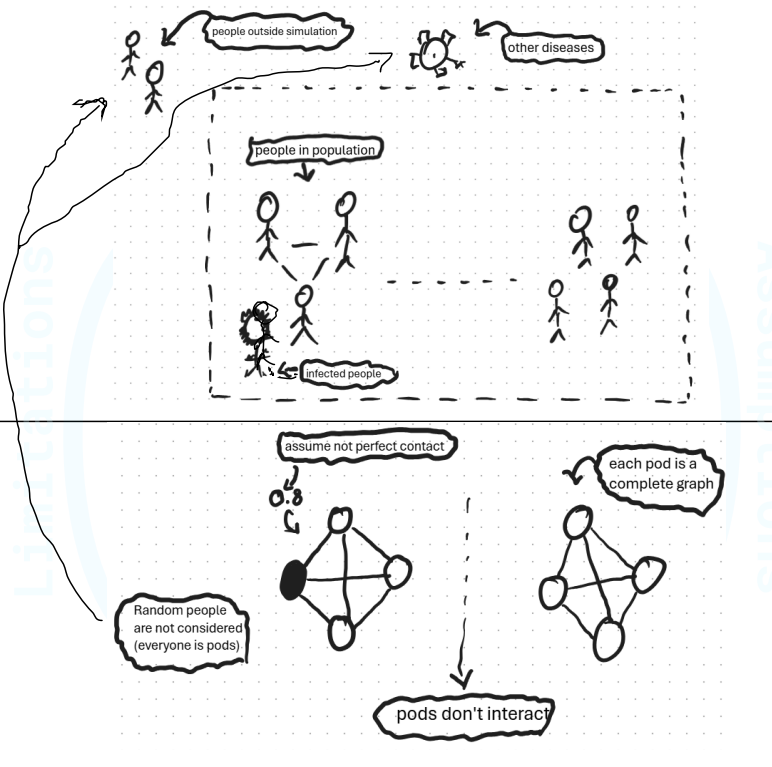

    Each agent could be susceptible, infected, or recovered. Interactions happen person-to-person in structured “pods” that represent social gatherings of fixed sizes. The people in each pod change every time step and agents don't always go to social gathering.

Here is the general overview of one simulation step:

- Agents who choose not to gather get temporarily removed from the dataset

- The remaining agents are randomly put into pods

- The infection simulation is run

- The data is merged back together

- All agents that are eligible to recover check to see if they do recover

There are a few assumptions and limitations worth noting.

- The social gathering "pods" are complete. In reality people may not have complete and equal contact with everyone at a social gathering. By having complete pods we assume a worst case scenario. We can still see the effects pods have though even with this limitation.

- The pods are fully isolated from eachother. While there may normally be some interaction between pods, we are assuming a quarantine-like situation where there are limited group sizes and interactions between people.

- The pods are all (mostly) the same size. As mentioned above, a lot of papers run models where there is a distribution of pod sizes each step. The pods in our model are all the same size (except for one overflow pod when the population is not divisible by the pod size). Although our method isn't completely accurate, we can still get data on how the different social gathering sizes affect disease spread.

- The agents are randomly put into pods. In the real world people are more likely to group with some people more often. Again, this is like assuming the worst case scenario where agents are constantly grouped with random people. The data can still offer insights about the effects of groups even when assuming the worst conditions.

Detailed model breakdown:

The whole model takes 7 input variables and outputs 3 variables.

The function $\textrm{simulate}\_\textrm{absir}\left(\right)$ is responsible for formatting these inputs and looping the $\textrm{action}\left(\right)$ function. For more details see [simulate_absir.m](https://github.com/derek-forgot/ModSim-Project2/blob/main/simulate_absir.m)

The first step of the action function is to remove an amount of the population proportional to the gathering chance.

Next $\mathrm{I}$ and $\mathrm{R}$ get scrambled. Note that the order is stored so that it may be unscrambled later

A function is then run to make a social graph that puts agents into pods.

If the population is not divisible by the pod size the function will make the last pod smaller. For more details see [pod_maker.m](https://github.com/derek-forgot/ModSim-Project2/blob/main/pod_maker.m)

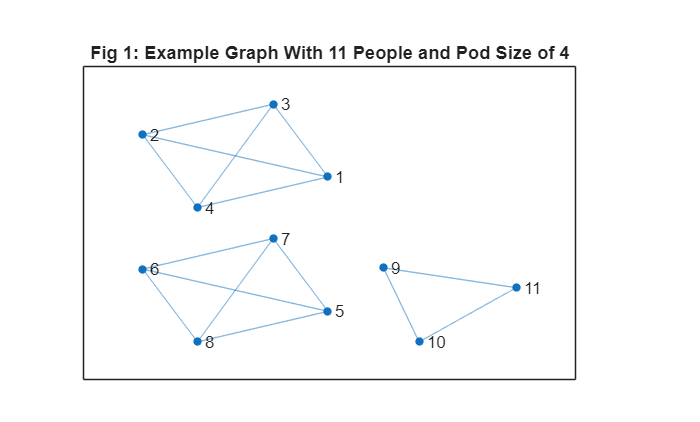

plot(graph(pod_maker(11,4))); title("Fig 1: Example Graph With 11 People and Pod Size of 4");

Fig 1 shows the pod maker working and adapting to indivisible group sizes.

With the social graph the infection probabilities can be computed.

Random values are drawn using this data for who gets infected and recovered. They are not yet applied to the data as there needs to be update rules. Also note that $\mathrm{v}\_\textrm{recover}$ is generated for the whole population as people who didnt gather could still recover.

The infected list is updated with the following rule: an agent is infected IF they are currently infected OR just got infected AND are not recovered. The list of people that become infected is stored so that they dont recover in the same step.

Next the lists are unscrambled.

The newly updated data is merged back together with the data of the people removed in the first step.

Finally, the recovery step is applied. An agent is recovered IF they are currently recovered OR they are infected AND recovered AND not just infected. The infected list is updated to remove people who are recovered.

Now that the function is defined we can do some verification to see that it works!

First we will check that all of the states always add up to the population. The exact numbers here don't matter but there will be a population of 100 people for 100 timesteps with 10 people initially infected.

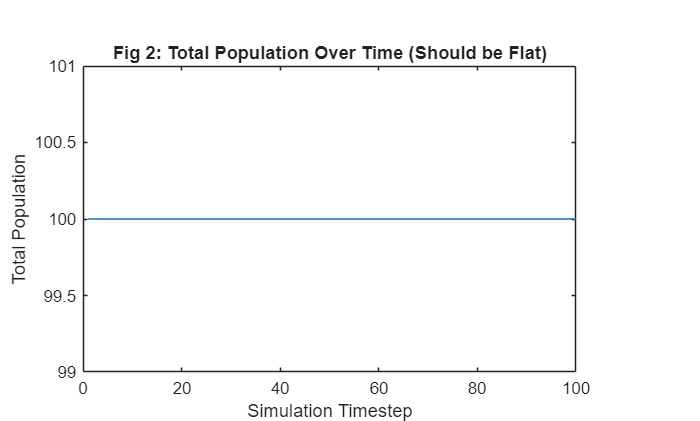

[Sh,Ih,Rh] = simulate_absir(100,(rand(100,1)<0.1),100,0.4,0.1,5,0.6);   %Run the simulation
working = sum(Sh,1) + sum(Ih,1) + sum(Rh,1);  %Sum susceptible, infected, and recovered per timestep
plot(working); title("Fig 2: Total Population Over Time (Should be Flat)"); xlabel("Simulation Timestep");ylabel("Total Population");    %Graph the results

Looking at Fig 2 we can see the population remaining constant. This can also be checked with an assert statement:

assert(all(working == working(1))); disp("Assertion passed, the population is the same at all timesteps");

Assertion passed, the population is the same at all timesteps


The population stays steady. Now we can check to see if people who become recovered stay recovered for the rest of the simulation. This will be done through graphing the recovery and checking that the recovery population never goes down.

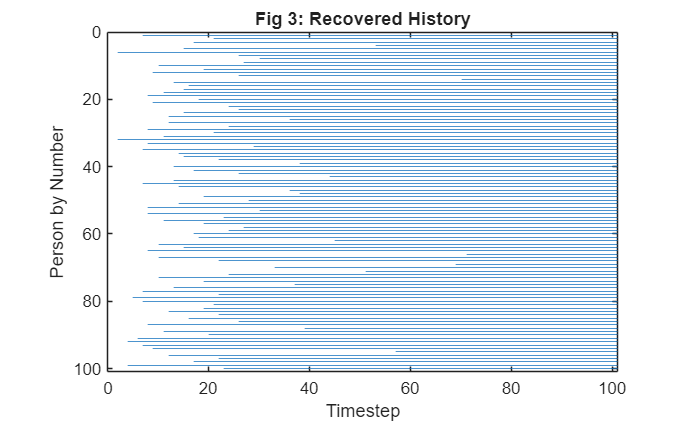

spy(Rh,"_"); title("Fig 3: Recovered History"); xlabel("Timestep"); ylabel("Person by Number"); pbaspect([3 2 1]);

Figure 3. shows that while some people take a while before recovering, nobody ever becomes un-recovered. This plot also confirms that the scramble and unscramble are functioning correctly as each agents keeps the same number. Again we can use an assert statement to double check that the recovered population doesn't go down.

assert(all(diff(sum(Rh,1))>=0));disp("Assertion passed, the recovered population never decreases")

Assertion passed, the recovered population never decreases


We can now do some validation with the research found earlier. The things to validate are:

- Smaller gathering sites generally produce lower and later infection peaks (Boyer et al.)

- Very large gatherings should lead to a higher rate of infections (Liu et al.)

- Reducing mobility (chance of gathering) should decrease transmission with consistent gathering sizes (Zhang, Taylor)

To compare our models results we need to decide on base parameters. The population count and timesteps are somewhat arbitrary. We will simulate 200 people for 100 timesteps. The infection rate is set to 0.4. This means that an infected person has a 40% chance of infecting a susceptible person. The recovery rate is put at 0.1 so that on average, it will take 10 days to recover. The chance of gathering is set to a reasonable 60%. The pod size also doesn't matter too much here so it will be set to 10. We will initialize the simulation with 10% of the population infected. The model will be run 100 times and averaged to help filter out randomness.

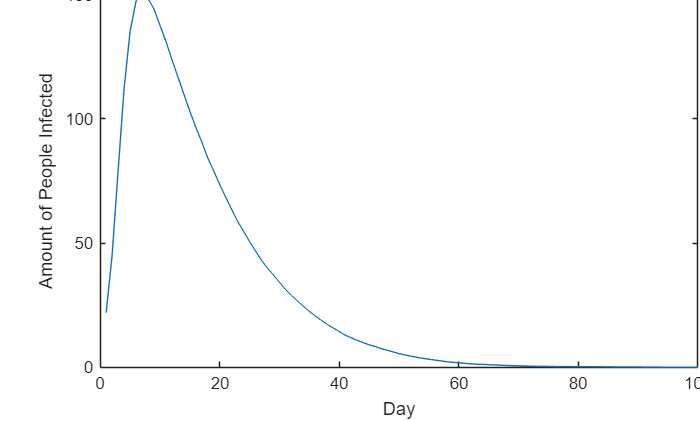

%Demo Variables
population = 200;
pod_size = 10;
time_steps = 100;
infection_rate = 0.4;
recovery_rate = 0.1;
gathering_chance = 0.6;
Iv0 = rand(population,1)<0.1;

%Run the simulation 100 times and average
for run=1:100
[~,Ih,~] = simulate_absir(population,Iv0, time_steps, infection_rate, recovery_rate,pod_size,gathering_chance);
baseline(run,:) = sum(Ih, 1);
end
baseline = mean(baseline,1);

%Plot
plot(baseline); title("Figure 4: Demo Run"); xlabel("Day");ylabel("Amount of People Infected");

Figure 4. shows that the model is running generally as expected.

Small gathering sizes, even at higher frequencies, generally produce lower and later infection peaks through reducing transmission opportunities. In our model, limiting pods to only two individuals slows down the rate of spread and flattens the infection curve, consistent with Boyer et al. (2022), who found that restricting social gathering sizes delays and lowers epidemic peaks by limiting potential contact chains. 

This trend is visible in Figure 5, where the curve for smaller gatherings rises more gradually and peaks later than the baseline, confirming that group-size restrictions slow transmission.

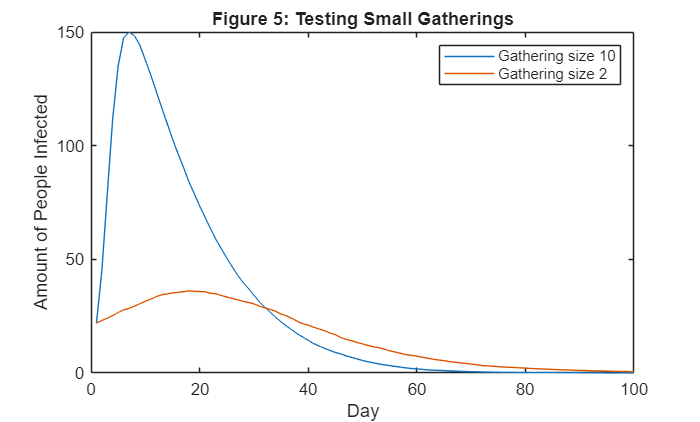

%Change the pod size to 2
pod_size = 2;

%Run the simulation 100 times and average
for run=1:100
[~,Ih,~] = simulate_absir(population,Iv0, time_steps, infection_rate, recovery_rate,pod_size,gathering_chance);
small_pod(run,:) = sum(Ih, 1);
end
small_pod = mean(small_pod,1);

%Plot
plot(baseline);hold on; plot(small_pod); title("Figure 5: Testing Small Gatherings"); xlabel("Day");ylabel("Amount of People Infected"); legend('Gathering size 10','Gathering size 2');hold off;

Figure 5. shows that pods of 2 rise more slowly and peak later and lower than size-10 pods, confirming Validation Fact 1 (Boyer et al., 2022).

Very large gatherings amplify transmission by creating dense contact networks that accelerate the spread of infection. When group sizes increase substantially, infection peaks become higher and occur earlier. This behavior reflects the findings of Liu et al. (2021), which showed that large-scale crowd events and gatherings drastically raise infection rates and shorten the time to peak cases.

The sharp spike in Figure 6 illustrates how large gatherings accelerate the spread, matching the theoretical prediction that increased density amplifies contact-driven infections.

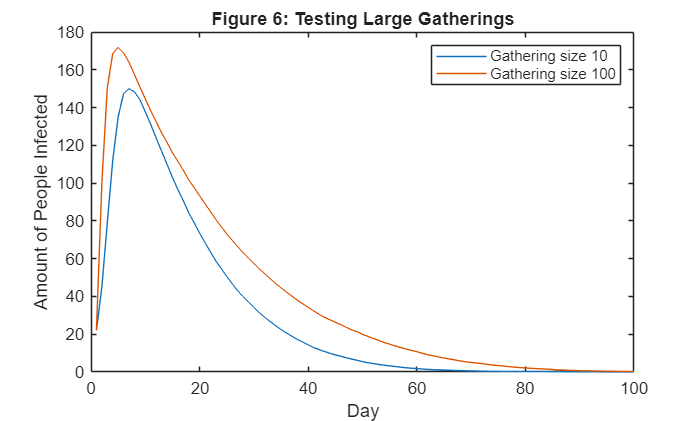

%Change the pod size to 100
pod_size = 100;

%Run the simulation 100 times and average
for run=1:100
[~,Ih,~] = simulate_absir(population,Iv0, time_steps, infection_rate, recovery_rate,pod_size,gathering_chance);
big_pod(run,:) = sum(Ih, 1);
end
big_pod = mean(big_pod,1);

%Plot
plot(baseline);hold on; plot(big_pod); title("Figure 6: Testing Large Gatherings"); xlabel("Day");ylabel("Amount of People Infected"); legend('Gathering size 10','Gathering size 100');hold off;

Figure 6. shows that size-100 pods cause a rapid surge with a much earlier, higher peak than size-10, consistent with Liu et al. (2021).

Reducing the frequency of social interactions has a strong mitigating effect on disease transmission. Even with fixed group sizes, lowering the probability that individuals attend gatherings significantly decreases and delays infection peaks. This aligns with Zhang and Taylor (2022), who demonstrated that reducing population mobility and contact frequency effectively suppresses epidemic spread and flattens the infection curve.

We see in figure 7 that lower gathering participation produces flatter curves, reinforcing that fewer overall interactions are key to reducing spread even without changing group size.

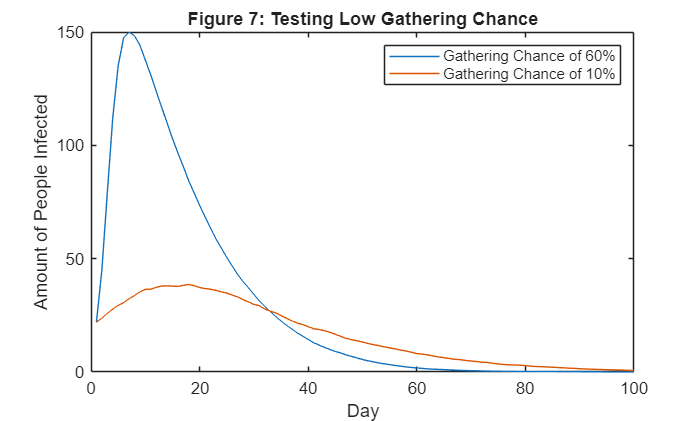

%Update variables
pod_size = 10;                  %Set the pod size back to 10
gathering_chance = 0.1;    %Set gathering chance to 10%

%Run the simulation 100 times and average
for run=1:100
[~,Ih,~] = simulate_absir(population,Iv0, time_steps, infection_rate, recovery_rate,pod_size,gathering_chance);
lo_chance(run,:) = sum(Ih, 1);
end
lo_chance = mean(lo_chance,1);

%Plot
plot(baseline);hold on; plot(lo_chance); title("Figure 7: Testing Low Gathering Chance"); xlabel("Day");ylabel("Amount of People Infected"); legend('Gathering Chance of 60%','Gathering Chance of 10%');hold off;

Figure 7. shows that reducing gathering chance from 60% to 10% flattens and delays infections at a fixed pod size of 10, validating the mobility effect (Zhang & Taylor, 2022).

## Results

    With the model validated, we can now use it to answer our question. To analyze how gathering size influences spread, we will perform a parameter sweep; varying pod sizes from 2 to 20. This parameter sweep directly answers the question: "How does limiting the size of social gatherings affect the rate of disease spread in a population?" For each pod size, the model will be run 100 times to get the average infected, susceptible, and recovered individuals over time. Comparing these curves will allow us to see how pod size affects disease spread. A population of 500 was chosen to give a more accurate simulation while also remaining runnable. Infection rate, recovery rate, and gathering chance were chosen to have minimal impact on the model. If they were set to extreme values the disease would immediately die or infect everyone.

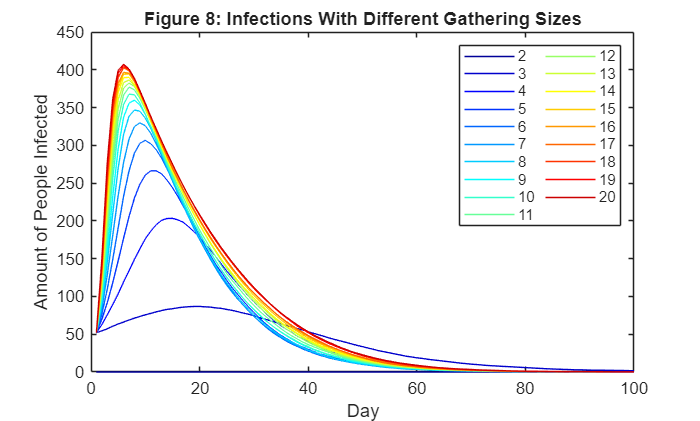

%Define variables
population = 500;
time_steps = 100;
infection_rate = 0.4;
recovery_rate = 0.1;
gathering_chance = 0.6;
Iv0 = rand(population,1)<0.1;


%The Big Sweep
for pods=2:20
    pod_size = pods;
    for run=1:100
        [Sh,Ih,Rh] = simulate_absir(population,Iv0, time_steps, infection_rate, recovery_rate,pod_size,gathering_chance);
        avgs(run,:) = sum(Sh, 1);
        avgi(run,:) = sum(Ih, 1);
        avgr(run,:) = sum(Rh, 1);
    end
    avg_pods(pods,:) = mean(avgs,1);
    avg_podi(pods,:) = mean(avgi,1);
    avg_podr(pods,:) = mean(avgr,1);
end

%Graph Infections
linecolors = jet(19);
for i=1:19
    plot(avg_podi(i,:),'color',linecolors(i,:));
    hold on;
end
title("Figure 8: Infections With Different Gathering Sizes"); xlabel("Day");ylabel("Amount of People Infected"); legend(["2", "3", "4", "5", "6", "7", "8", "9", "10", "11", "12", "13", "14", "15", "16", "17", "18", "19", "20"], 'NumColumns',2); hold off;

Figure 8 shows the average infection histories for each gathering size. In this simulation we can see that large gatherings lead to significantly higher, faster infection peaks, while smaller pods have lower, slower infection peaks

## **Interpretation**

    In all simulations we ran, we observed that larger gatherings led to significantly higher, faster infection peaks, while smaller pods had lower, slower infection peaks. The effectiveness of limiting gathering sizes is not linear though. With very small groups the infection curve rose gradually and peaked at a much lower level, showing that limiting gatherings effectively suppressed transmission. But past a certain point the differences became negligable. Group sizes past 10 all had peaks infections withing 8% of eachother. This is not to say that 10 is the magic number but that there does exist a point to which limiting groups size doesnt change anything.

    Looking ahead our model could be further validated with real world parameters. This validation in combination with a more complex model like SIRVD might allow someone to definitively know what the ideal maximum gathering size is during a pandemic.

## AI Statement:

  AI was not used during this project.